Load data file (struct 3D format) and get axes order

% FolderPath = ['C:\Users\' getenv('USERNAME') '\Google Drive\MATLAB Drive\vars'];
FolderPath = 'D:\Google Drive\MATLAB Drive\vars';
SampleName = 'B5 b7 150um 4';
SweepID = 'M4T1';
A = (150^2 * pi)*1e-8;
FileName = [SampleName ' ' SweepID];
SetName = '3D_sweep_order';
RealPath = [FolderPath '\' SampleName '\' FileName];
%RealPath = '' % Or put the path yourself

LoadedFile = load(RealPath)

LoadedFile = struct with fields:
                 full_struct_vec_offset_frequency_amplitude: [1×126 struct]
    select_data_3D_desired_order_offset_frequency_amplitude: [1×1 struct]
      select_data_3D_sweep_order_frequency_amplitude_offset: [1×1 struct]


fNames = fieldnames(LoadedFile);
DataStruct0 = LoadedFile.(fNames{contains(fNames, SetName)});
Order = DataStruct0.order;
% StrBeforeOrder = 'order_'; % input the string just before the first parameter
% Order = MFIA_get_order_from_path(fNames{contains(fNames,SetName)}, StrBeforeOrder)
title = RealPath(sum(find(RealPath=='\', 1, 'last'))+1:end)

title = 'B5 b7 150um 4 M4T1'


SavePlotPath = [FolderPath '\' SampleName '\' title];

Process (define range and limits) and optionally plot data

Save data slice plots

SaveDataPlots = false;

Select data to plot (leave empty to plot all data in 3D struct) and define plot aliases (from IA parametric model)

plt_select_data = {};
% plt_select_data(:,end+1) = {'param0'; 'Resistance [ohm]'};
plt_select_data(:,end+1) = {'param1'; 'Capacitance [F]'};
% plt_select_data(:,end+1) = {'absz'; 'Impedance Magnitude [ohm]'};
% plt_select_data(:,end+1) = {'phasez'; 'Impedance Phase'};

Select axis range - data outside range is discarded from here onward (applies to all subsequent fits)

ax_range = {};
ax_range(:,end+1) = {'frequency'; [0 inf]};
ax_range(:,end+1) = {'amplitude'; [0 inf]}; 
ax_range(:,end+1) = {'offset'; [-inf inf]};

Select value range - data outside range is replaced with NaN from here onward (applies to all subsequent fits)

val_range = {};
val_range(:,end+1) = {'param0'; [0 inf]};
val_range(:,end+1) = {'param1'; [0 inf]};

Define slice planes

slice_planes = {};
slice_planes(:,end+1) = {'frequency'; [1e2 1e3 1e4 1e5 5e5]};
slice_planes(:,end+1) = {'amplitude'; []}; 
slice_planes(:,end+1) = {'offset'; [0 -0.1 -0.2 -0.5 -1 -1.5]};

Add plot formatting commands:

all: plt_cmds(2,end+1) =  {'comand'}; '' for ' inside string.

target: plt_cmds(:,end+1) =  {'target' ; 'comand'};

plt_cmds = {};
% plt_cmds(2,end+1) = {'grid on'};
plt_cmds(2,end+1) = {'colorbar(''eastoutside'')'};
plt_cmds(2,end+1) = {'colormap(s,''turbo'')'};
plt_cmds(2,end+1) = {'colormap(s,interp1(colormap(s), 1:(length(colormap(s))/998):length(colormap(s))))'};
plt_cmds(:,end+1) = {'param0'; 'colormap(s,[compress_array_exp(colormap(s),10,10, ''Reverse'', true, ''Interp'', true)])'};
% plt_cmds(2,end+1) = {'colormap(s,[0 0 0; colormap(s)])'};
% plt_cmds(2,end+1) = {'colormap([colormap; 1 1 1])'};
plt_cmds(:,end+1) = {'param0'; 'caxis([0 1e7])'};
plt_cmds(:,end+1) = {'param1'; 'caxis([0 inf])'};

plt_log_freq = true; % true for log plot frequency
if plt_log_freq
    Order{contains(Order, 'frequency')} = 'log_frequency';
    ax_range(:,contains(ax_range(1,:), 'frequency')) = {'log_frequency'; log10(ax_range{2,contains(ax_range(1,:), 'frequency')})};
    slice_planes(:,contains(slice_planes(1,:), 'frequency')) = {'log_frequency'; log10(slice_planes{2,contains(slice_planes(1,:), 'frequency')})};
end

Plot slice planes of 3D data

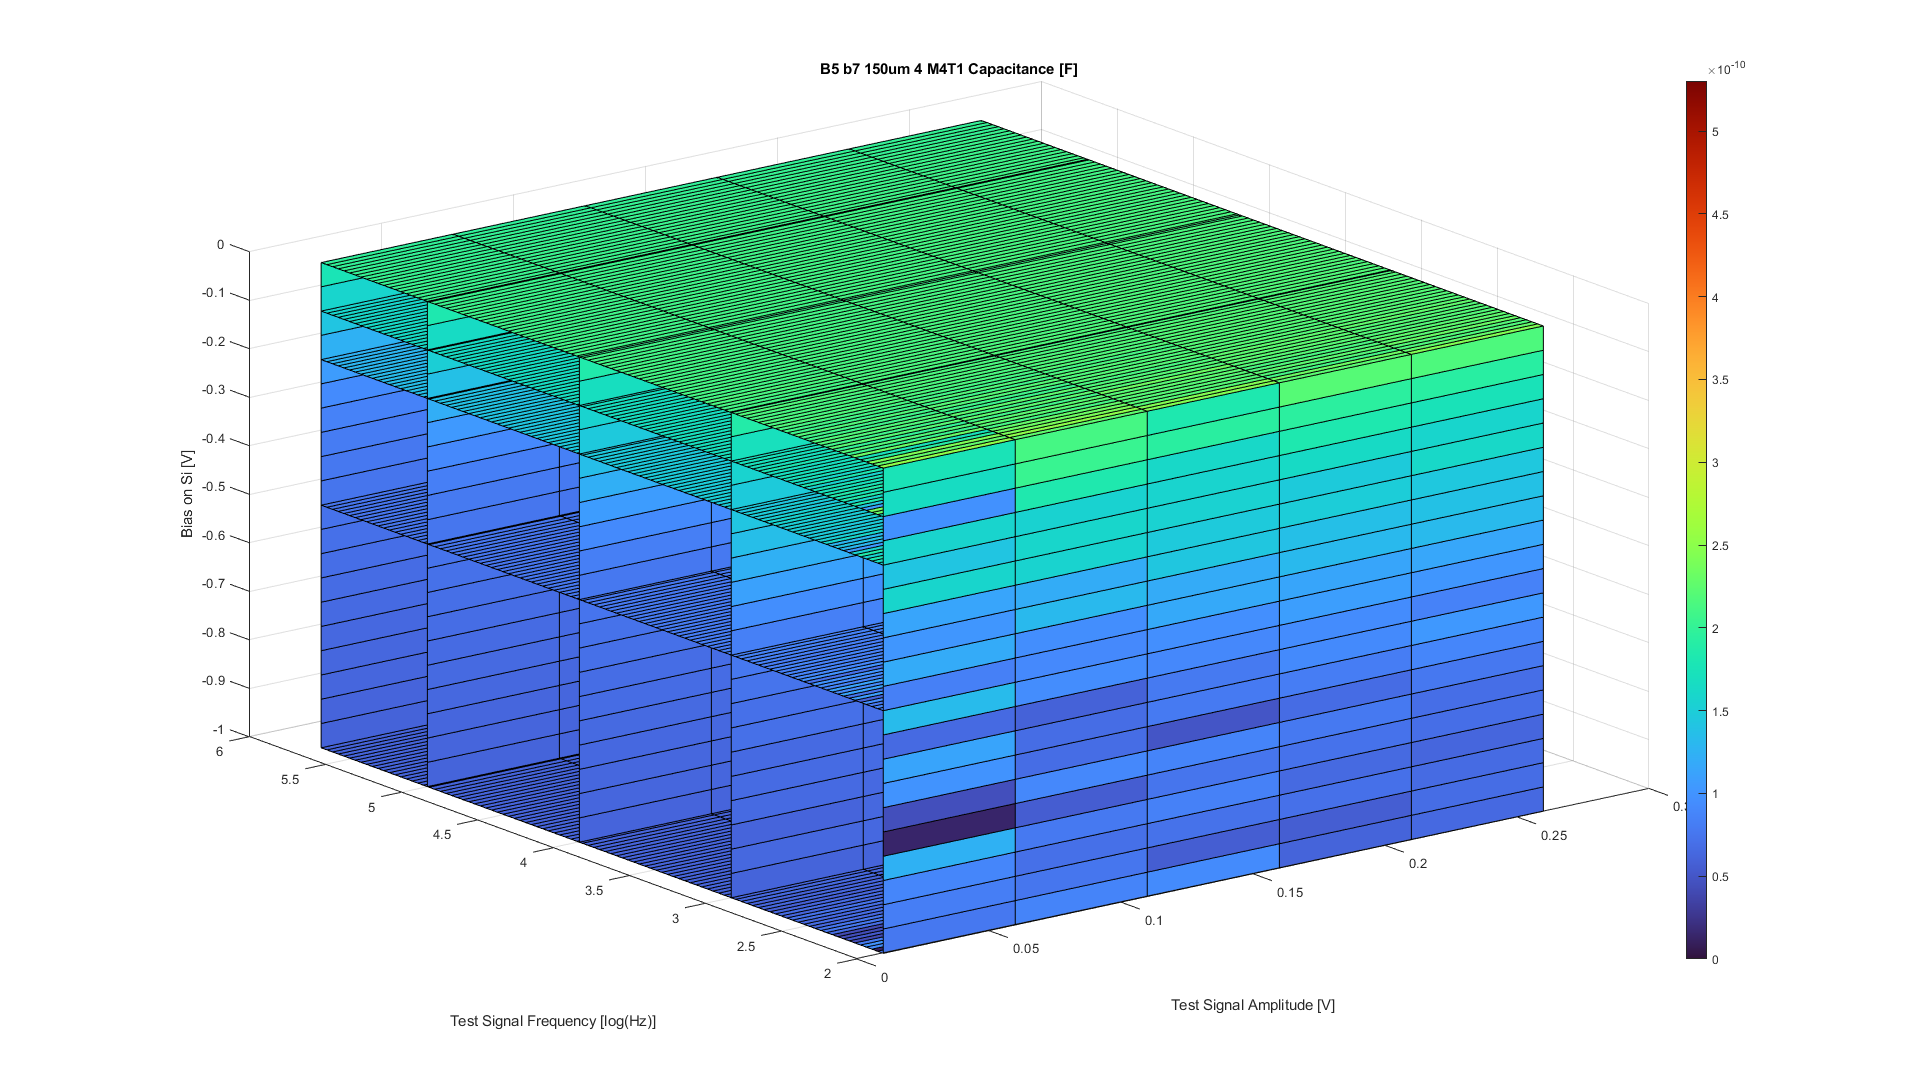

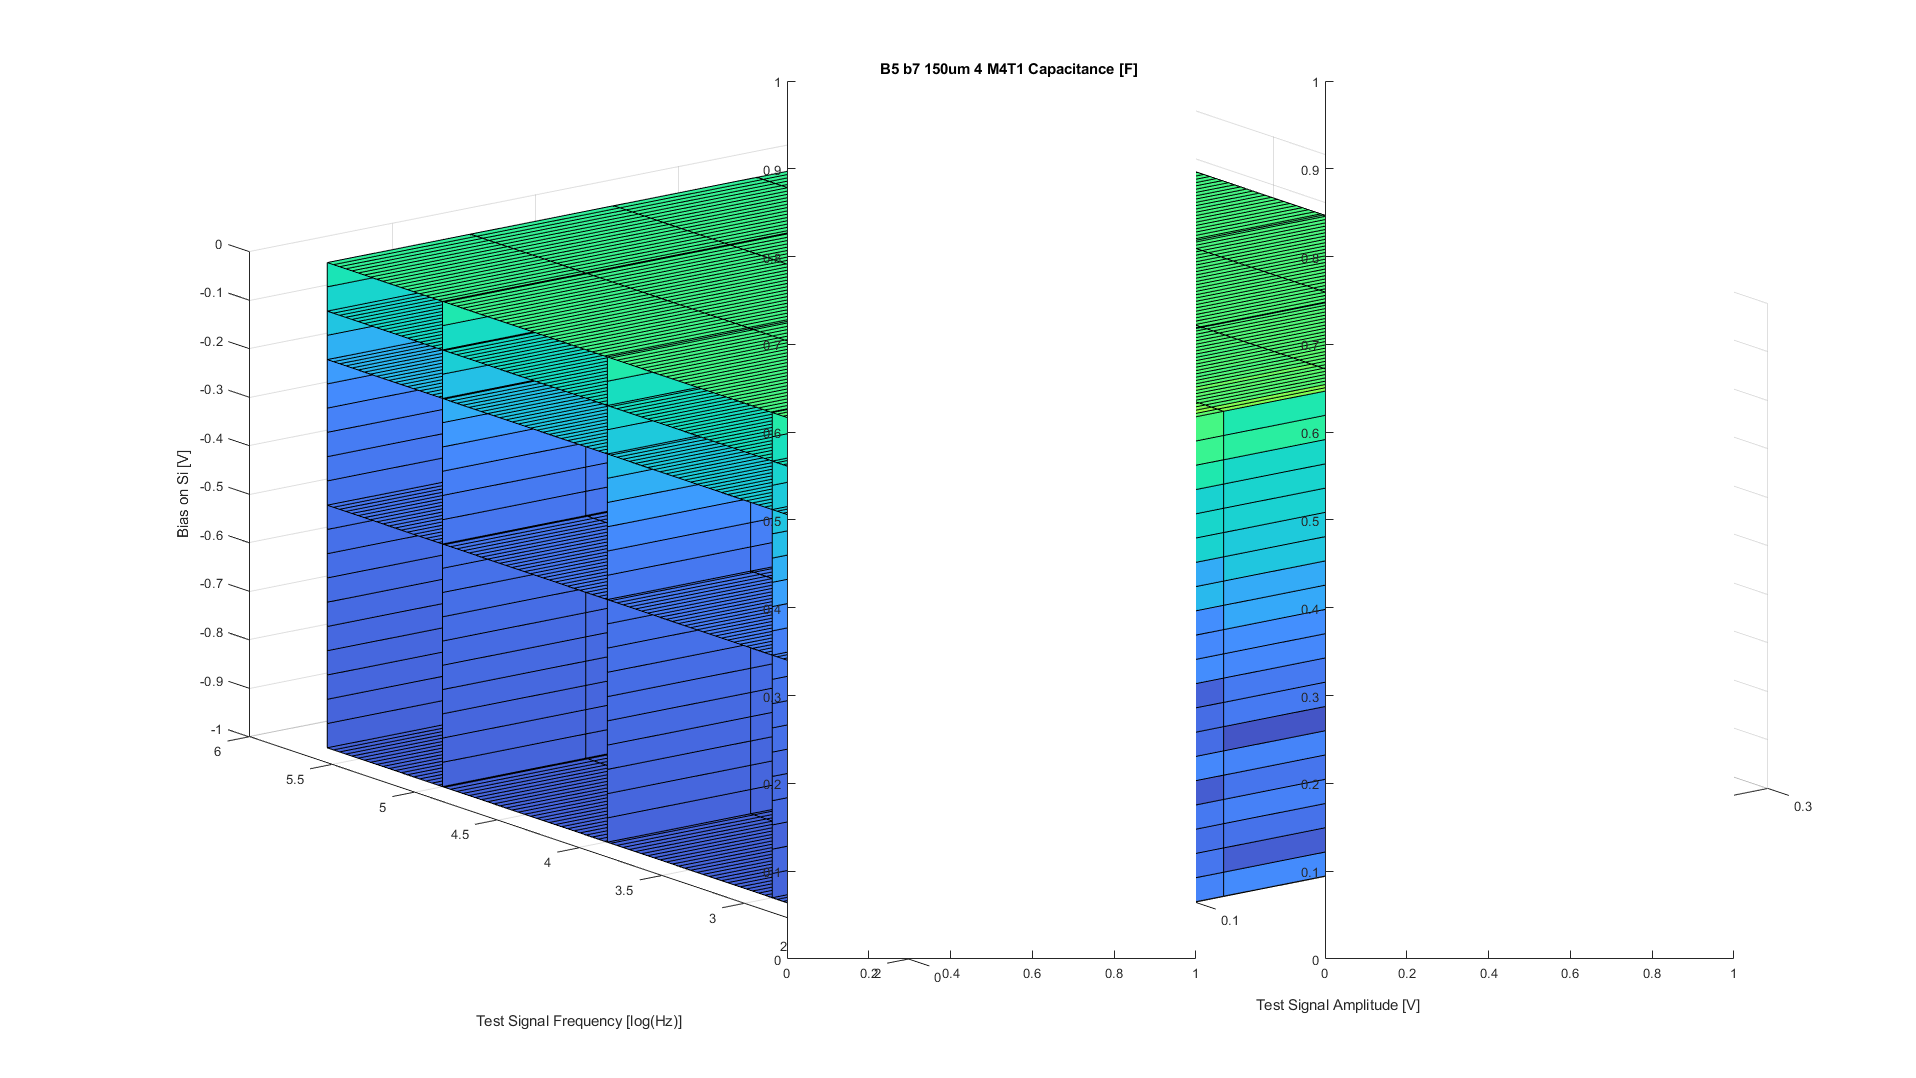

[PlotFig, SubPlots, DataStruct,~,~,ND] = process_plot_struct_data3D(DataStruct0, Order, slice_planes, 'title', title, 'ax_range', ax_range, 'val_range', val_range, 'plt_select_data', plt_select_data, 'plt_cmds', plt_cmds);
PlotGUI = MFIA_PGUI(SubPlots,ND);

if SaveDataPlots
    StartTime = datestr(now, 'yyyy-mm-dd HH-MM-SS');
    if ~isfolder([SavePlotPath '\Slice Plots'])
        mkdir([SavePlotPath '\Slice Plots']);
    end
    f=figure('Position',get(0,'Screensize'));
    copyobj(get(PlotFig, 'Children'),f)
    f.Visible = 'on';
    saveas(f, [SavePlotPath '\Slice Plots\' FileName ' slice_plot ' StartTime '.fig']);
    f.Visible = 'off';
    saveas(f, [SavePlotPath '\Slice Plots\' FileName ' slice_plot ' StartTime '.bmp']);
    close(f)
    if ~isfolder([SavePlotPath '\GUI'])
        mkdir([SavePlotPath '\GUI']);
    end   
    saveas(PlotGUI, [SavePlotPath '\GUI\' FileName ' GUI ' StartTime '.fig']);
end

## Fit data along a certain dimension

## CV fit

**Fit, plot and save options**

Save_CV_plot = true;

CV_plot_fit = [];
CV_plot_fit.func = @plot;
CV_plot_fit.visible = 0;
CV_plot_fit.screensize = 0;
CV_plot_fit.savepath = SavePlotPath;
CV_plot_fit.properties = {'Marker','o', 'LineStyle','none'};
% CV_plot_fit = [];

CV_fit_select = {'capacitance'};
CV_fit_axis = 'offset';

CV_val_range = {};
CV_val_range(:,end+1) = {''; [0 inf]};
CV_val_range(:,end+1) = {''; [0 inf]};

**Fit function and options**

CV_offset_Range = [-1 -0.5];
CV_str = ['Fit range= ' sprintf('%0.3g ',CV_offset_Range)];
CV_FitProp = {'Robust','Bisquare'};
syms V N Vb n
limits_A = {'Vb',[0 0.5 1],'N',[1e16 2e18 5e18],'n',[1 3 10]};
limits_A = {};
n=1;
CV_str = [strAdd('n',n, 'N',N, 'Vb',Vb, CV_FitProp{:}) ' ' CV_str];
es = 11.68;
CV_fit_func = @(x,y) C_schot_fit_A(x,y,CV_offset_Range,A,es,N,Vb,n,CV_FitProp,limits_A{:});

[CV_fig, CV_sbp, CV_struct_array, CV_FitAppendPath, CV_FitName] = fit_cell_3D(DataStruct.data, DataStruct.axes, CV_fit_func, CV_fit_axis, 'plt_select_data',CV_fit_select, 'title',title, 'plot_fit',CV_plot_fit, 'val_range',CV_val_range, 'str',CV_str);
CV_GUI = MFIA_PGUI(CV_sbp,2);
if Save_CV_plot
    CV_save_path = [SavePlotPath '\' CV_FitAppendPath];
    mkdir(CV_save_path);
    save([CV_save_path '\CV fit out ' CV_FitName], 'CV_struct_array')
    f=figure('Position',get(0,'Screensize'));
    copyobj(get(CV_fig, 'Children'),f)
    f.Visible = 'on';
    saveas(f, [CV_save_path '\CV fit ' CV_FitName '.fig']);
    f.Visible = 'off';
    saveas(f, [CV_save_path '\CV fit ' CV_FitName '.bmp']);
    close(f)
    saveas(CV_GUI, [CV_save_path '\CV fit GUI ' CV_FitName '.fig']);
end

## DLCP Fit

**Fit, plot and save options**

Save_DLCP_plot = false;

DLCP_plot_fit = [];
DLCP_plot_fit.func = @plot;
DLCP_plot_fit.visible = 0;
DLCP_plot_fit.savepath = SavePlotPath;
DLCP_plot_fit.properties = {'Marker','o', 'LineStyle','none'};
DLCP_plot_fit = [];

DLCP_fit_select = {'capacitance'};  
DLCP_fit_axis = 'amplitude'; 

DLCP_val_range = {};
DLCP_val_range(:,end+1) = {'N'; [0 5e19]};

**Fit function and options**

DLCP_amplitude_Range = [0.05 0.15];
DLCP_str = ['Fit range= ' sprintf('%0.3g ',DLCP_amplitude_Range)];

DLCP_fit_func = @(x,y) DLCP_fit(x,y, A, 'range',DLCP_amplitude_Range);

[DLCP_fig, DLCP_sbp, DLCP_struct_array, DLCP_FitAppendPath, DLCP_FitName] = fit_cell_3D(DataStruct.data, DataStruct.axes, DLCP_fit_func, DLCP_fit_axis, 'plt_select_data',DLCP_fit_select, 'title',title, 'plot_fit',DLCP_plot_fit, 'val_range', DLCP_val_range, 'str',DLCP_str);
DLCP_GUI = MFIA_PGUI(DLCP_sbp,2);
if Save_DLCP_plot
    DLCP_save_path = [SavePlotPath '\' DLCP_FitAppendPath];
    mkdir(DLCP_save_path);
    save([DLCP_save_path '\DLCP fit_out ' DLCP_FitName], 'DLCP_struct_array')
    f=figure('Position',get(0,'Screensize'));
    copyobj(get(DLCP_fig, 'Children'),f)
    f.Visible = 'on';
    saveas(f, [DLCP_save_path '\DLCP fit ' DLCP_FitName '.fig']);
    f.Visible = 'off';
    saveas(f, [DLCP_save_path '\DLCP fit ' DLCP_FitName '.bmp']);
    close(f)
    saveas(DLCP_GUI, [DLCP_save_path '\DLCP fit GUI ' DLCP_FitName '.fig']);
end

## Functions

function str = strAdd(varargin)
str = '';
for i=1:2:length(varargin)
    c = varargin{i+1};
    if isnumeric(c)
        str = [varargin{i} '=' num2str(c,2) ' ' str];
    elseif isstring(c) || ischar(c)
        str = [varargin{i} '=' c ' ' str];
    end
end
end